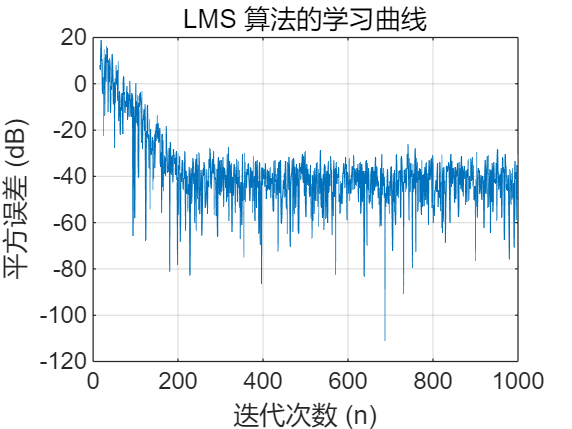

clc;
clear;
close;

N = 1000;
M = 16;
mu =0.02;

%产生信号
x = randn(N,1);%激励信号，高斯白噪声
h_true = randn(M,1);%未知系统的真值(目标预测的系数)
d = filter(h_true,1,x) + 0.01*randn(N,1);%期望信号 = 真实输出 + 观测噪声

%初始化
w = zeros(M,1);
e = zeros(N,1);
y = zeros(N,1);%输出记录

%LMS循环
for n = M : N 
    %提取输入向量
    x_n = x(n:-1:n-M+1);

    %计算输出
    for i = 1:M
        y(n) = y(n)+w(i)*x_n(i);
    end
    %计算误差
    
    e(n) = d(n) - y(n);
    %更新权重
    w = w + 2*mu*e(n)*x_n;


end

figure;
plot(10*log10(e.^2)); % 转化为 dB 尺度
grid on;
title('LMS 算法的学习曲线');
xlabel('迭代次数 (n)');
ylabel('平方误差 (dB)');

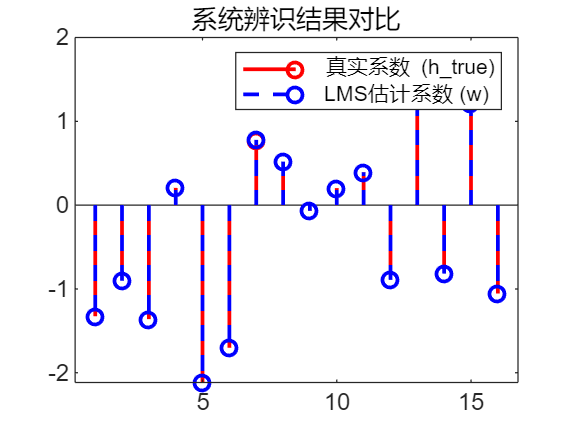


figure;
stem(h_true, 'r', 'LineWidth', 1.5); hold on;
stem(w, 'b--', 'LineWidth', 1.5);
legend('真实系数 (h\_true)', 'LMS估计系数 (w)');
title('系统辨识结果对比');

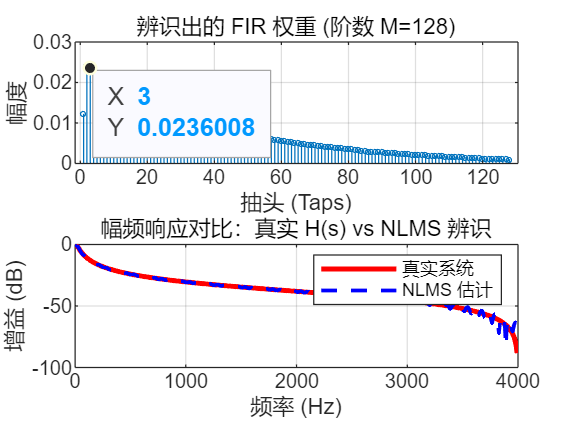

clc; clear; close all;

% --- 1. 环境与系统设置 ---
fs = 8000;              % 采样率
T = 1.5;                % 运行1.5秒，给足够的收敛时间
t = (0:1/fs:T).';
N = length(t);

% 定义连续系统 H(s) = a / (s + a)
a = 200;                % 截止频率 (rad/s)
sys_c = tf(a, [1, a]);
sys_d = c2d(sys_c, 1/fs, 'tustin'); % 离散化

% 获取离散系统的分子分母系数（用于产生期望信号）
[num, den] = tfdata(sys_d, 'v');

% --- 2. 产生信号 ---
x = randn(N, 1);        % 输入：白噪声（全频率激励）
d = filter(num, den, x);% 期望：白噪声通过低通系统后的输出

% --- 3. NLMS 算法初始化 ---
M = 128;                % 滤波器阶数（捕捉系统细节）
w = zeros(M, 1);        % 初始权重
e = zeros(N, 1);        % 误差
mu = 0.05;              % 你建议的小步长（为了高精确度）
eps_val = 1e-10;

% --- 4. NLMS 核心循环 ---
for n = M : N
    x_n = x(n:-1:n-M+1);% 提取当前的输入窗口
    
    y_n = w' * x_n;     % 预测系统的输出
    e(n) = d(n) - y_n;  % 误差：真实系统输出 - 预测输出
    
    % NLMS 更新公式
    norm_x = x_n' * x_n;
    w = w + (mu / (norm_x + eps_val)) * e(n) * x_n;
end

% --- 5. 结果绘图 ---
figure('Color', 'w', 'Name', '系统辨识实验');

% A. 观察辨识出的冲激响应 (权重 w)
subplot(2,1,1);
stem(w, 'MarkerSize', 2);
title(['辨识出的 FIR 权重 (阶数 M=', num2str(M), ')']);
xlabel('抽头 (Taps)'); ylabel('幅度');
grid on;

% B. 观察频率响应的拟合程度
[H_est, f] = freqz(w, 1, 512, fs);              % 辨识出的
[H_true, ~] = freqz(num, den, 512, fs);         % 真实的
subplot(2,1,2);
plot(f, 20*log10(abs(H_true)), 'r', 'LineWidth', 2); hold on;
plot(f, 20*log10(abs(H_est)), 'b--', 'LineWidth', 1.5);
title('幅频响应对比：真实 H(s) vs NLMS 辨识');
xlabel('频率 (Hz)'); ylabel('增益 (dB)');
legend('真实系统', 'NLMS 估计');
grid on;